## Wavelet Transform FUN!!!

Brittany Scheid (bscheid@seas.upenn.edu), Last Updated: 12/2020

The following script explores the wavelet transform, wavelet coherence, and cross wavelet transform functions with a few intuition-building examples.

 Functions used here can be found in the **Cross wavelet and wavelet coherence toolbox for MATLAB: **[https://github.com/grinsted/wavelet-coherence,](https://github.com/grinsted/wavelet-coherence,) and more information can be found in the associated paper:

Grinsted, A., J. C. Moore, S. Jevrejeva (2004), Application of the cross wavelet transform and wavelet coherence to geophysical time series, Nonlin. Process. Geophys., 11, 561566  [link](http://www.glaciology.net/Home/PDFs/Announcements/Application-of-the-cross-wavelet-transform-and-wavelet-coherence-to-geophysical-time-series-)

### Building Intuition: Spectral Power Density 

In the first example, we will take two functions that have linearly increasing and decreasing frequencies respectively (these are called chirps because of how they sound... play this section with your speakers on), and explore their spectrogram, wavelet transform, cross wavelet transform, and wavelet coherence:

fs = 1000; % sampling frequency
t = linspace(0,5,5*fs); 
y1 = chirp(t,0,5,100); % Builds signal with linearly increasing frequency from 0 to 100
y2 = flip(y1); 

plot(t, y1, t, y2); title('y1 and y2 in time domain')
plot(t, y1); title('y1 zoomed in'); xlim([0,1])

% Take a look at their spectrograms:
spectrogram(y1, [], [], [], fs, 'yaxis'); title('y1 (freq. increasing) spectrogram')
spectrogram(y2, [], [], [], fs, 'yaxis'); title('y2 (freq. decreasing) spectrogram')

% Listen to the chirps!
sound(y1, fs*20); pause(1)
sound(y2, fs*20);


To build some intuition, we first take a look at the signals' spectrograms. The spectrogram function splits the signal into time windows, then within a window the signal is separated into its frequency components and the power (# of sine waves) is quantified at each frequency. This calculation (called the power spectral density, PSD), is calculated for each time window such that the spectrogram gives you a plot of PSD over time. 

The pwelch function below returns the power spectral density of the entire signal. Since we know that the signal has frequency increasing linearly from 0 to 100, it makes sense that we have high power in the 0 to 100 range, and low power after that. Likewise, if we take the PSD of a single window of the signal, we only see high power for frequencies represented within that window. 

pwelch(y1, [], [], [], fs) % Power in full signal
pwelch(y1(end/4:(end/8*3)), [], [], [], fs) % power in second eight of the signal

### The Wavelet Transform 

Now it's time to take a look at the wavelet transforms of the functions. The wavelet transform output is similar to the spectrogram, however the method used to filter the signal at each frequency band is different, and here uses a frequency-dependent "Morlet wavelet" to pull out the correct frequency. The Morlet wavelet is just one of many different types of wavelets that could be used. In general I like to think of wavelet filters as stencils that you can slide across a signal and will give you a higher value when the shape of signal is a better match to the filter. One concrete example of this would be using wavelet transforms to detect EKG waves. Basically, wavelets can be used to recognize arbitrary waveforms, and the Morlet wavelet is just a particular pattern used to recognized sign waves at a given frequency. 

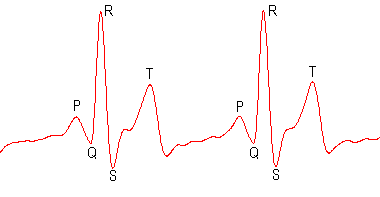

[psi,xval]= morlet(-4, 4, 1000);
plot(xval,psi)
grid on
title('Morlet Wavelet')

Note the log scale on the y-axis of the wavelet transforms of our "chirp" functions. This is why the line looks more like f=log(t), instead of a linear function. 

wt(y1); title('wavelet transform y1 (freq. increasing)')
wt(y2); title('wavelet transform y2 (freq. increasing)')

wt(y1+y2); title('wavelet transform y1 + y2')

### The Cross Wavelet Transform 

The cross wavelet transform takes two signals as an input, and will be high when the spectrograms (or wavelet transforms) of both the signals are high. Phase arrows indicate the relative phase relationship between the time series series (pointing right: in-phase; left: anti-phase), we will play with phase arrows later. 

xwt(y1, y2)

As you can see, the area where the wavelet transforms for each signal overlapped is where we see the greatest value of the cross wavelet transform. 

And what pray tell is the shaded part on the edges of the image? 'Tis:

load('props/info.mat')
soundsc(coi, coi_fs); pause(5)

WAIT, WHAT WAS THAT??!?

soundsc(coi, coi_fs/1.5); pause(8)

oh. I see. (The shaded regions at low frequencies/large periods suffer from edge effects and aren't reliable)

### Wavelet Transform Coherence

Now finally, we get to wavelet transform coherence! The wavelet transform coherence takes in two signals, and gives you a measure of similarity of the the wavelet transforms of the two signals at each time point and frequency value. The wavelet transform coherence is sensitive to how consistently a given frequeny is represented by both signals, looking for locally phase-locked behavior. This is illustrated even more clearly in Example 2.

wtc(y1, y2, 'MonteCarloCount', 1)

### Example 2: Pure sinusoidal functions

For this next exploration, we will take a look at what happens when we work with pure, ideal sine waves. Lets say we have one at 10 hz, and one at 20 hz, and one at 100 Hz. For each function, power should be localized to the function's main frequency band. 

Y10hz = sin(t*2*pi*10);  % 10 Hz sign wave
Y20hz = sin(t*2*pi*20);  % 20 Hz sign wave
Y100hz = sin(t*2*pi*100); % 100 Hz sign wave

plot(t, Y10hz, t, Y20hz, t, Y100hz)
xlim([0,.1]); title('Sine waves at 10, 20, & 100Hz (zoomed in)'); xlabel('time')
legend({'10Hz', '20Hz', '100Hz'})


Self test: 

- what do you think the power spectral density (PSD) will look like when all signals are added? 

- What do you think the spectrogram will look like? 


pwelch(Y10hz + Y20hz + Y100hz, [], [], [], fs)                % Power of 3 combined signals
spectrogram(Y10hz + Y20hz + Y100hz, [], [], [], fs, 'yaxis')  % spectrogram of 3 combined signals



Now we plot the wavelet transforms of the sine waves independently, and also of two pairs of sine waves (the 10Hz and 20Hz, and the 10Hz and 100Hz):

figure(1); clf;
subplot(2,2,1); 
wt(Y10hz); 
title('10 Hz wt'); 

subplot(2,2,3)
wt(Y20hz); 
title('20 Hz wt'); 
subplot(2,2,[2,4])
wt(Y20hz+Y10hz); 
title('10 + 20 Hz wt')


figure(2); clf;
subplot(2,2,1); 
wt(Y10hz); 
title('10 Hz wt')
subplot(2,2,3)
wt(Y100hz); 
title('100 Hz wt')
subplot(2,2,[2,4])
wt(Y100hz+Y10hz); 
title('10 + 100 Hz wt')



The cross wavelet transform and wavelet coherence for each pair are shown as follows: 

figure(3); clf;
subplot(2,2,1)
xwt(Y10hz, Y20hz); title('xwt 10hz, 20hz')
subplot(2,2,2)
wtc(Y10hz, Y20hz, 'MonteCarloCount', 1)
title('wtc 10hz, 20hz')

subplot(2,2,3)
xwt(Y10hz, Y100hz); title('xwt 10hz, 100hz')
subplot(2,2,4)
wtc(Y10hz, Y100hz, 'MonteCarloCount', 1)
title('wtc 10hz, 100hz')



## Playing with Phase

And finally, what is the deal with the arrows? The arrows illustrate the phase lead or lag between the two signals. We can illustrate this with another basic sine wave example and a slider. 

offset=0

Y10hz_offset = sin(t*2*pi*10 - (2*pi*offset/10));

figure(4)
plot(t,Y10hz, t, Y10hz_offset)
xlim([0,1])
legend({'Y10Hz', 'Y10Hz shifted'})

xwt(Y10hz, Y10hz_offset); title('xwt 10hz, 10hz offset')


Set the slider to 0 offset, and the arrows should be pointing to the right. Move the slider to 5, (exactly anti-phase), and the arrows will point left. At an offset of 2.5 (the shifted signal is *leading* our original signal), the arrows move clockwise a quarter turn. Likewise at an offset of 7.5 (equivilant to -2.5), the shifted signal is *lagging* behind our original signal. 

### Final Words

As a reminder, this script is far from an exhaustive review of the wavelet transform and its behaviors. There are quite a few knobs that can be adjusted which we haven't looked at here, including the choice of wavelet, the window resolution, the smoothing function chosen to calculate wavelet coherence, and the method of calculating both intensity and phase significance. 